## **2.1 Анализ матриц**

**Система**

m = 1;
M = 10;
g = 9.8;
l = 0.5;

A =[0, 1, 0, 0;
   0, 0, m*g/M, 0;
   0, 0, 0, 1;
   0, 0, (M+m)*g/(M*l), 0];
B =[0;1/M;0;1/(M*l)];
C =[1,0,0,0;
    0, 0, 1, 0];
D =[0; 1/(l*M); 0; (M+m)/(m*M*l^2)];

Собственные числа и собственные векторы матрицы А

eig(A)

ans =          0
         0
    4.6433
   -4.6433


[V, Y] = eig(A)

V =     1.0000   -1.0000    0.0096   -0.0096
         0    0.0000    0.0444    0.0444
         0         0    0.2103   -0.2103
         0         0    0.9766    0.9766


Y =          0         0         0         0
         0         0         0         0
         0         0    4.6433         0
         0         0         0   -4.6433


Анализ системы на управляемость

U = ctrb(A, B)

U =          0    0.1000         0    0.1960
    0.1000         0    0.1960         0
         0    0.2000         0    4.3120
    0.2000         0    4.3120         0


rank(U)

ans = 4

Анализ системы на наблюдаемость

V = obsv(A, C)

V =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
         0         0    0.9800         0
         0         0   21.5600         0
         0         0         0    0.9800
         0         0         0   21.5600


rank(V)

ans = 4

## **2.2 Передаточные функции**

syms s
W_uy = simplify(C*inv(s*eye(4) - A)*B)

$$W\_uy = \left(\begin{array}{c} \frac{5\,s^{2}-98}{2\,s^{2}\,\left(25\,s^{2}-539\right)}\\ \frac{5}{25\,s^{2}-539} \end{array}\right)$$

W_fy = simplify(C*inv(s*eye(4) - A)*D)

$$W\_fy = \left(\begin{array}{c} \frac{5}{25\,s^{2}-539}\\ \frac{110}{25\,s^{2}-539} \end{array}\right)$$

Полюса передаточных

numerator = [5, 0, -98];
denominator = [2*25,0, -2*539, 0, 0];
sys1 = tf(numerator,denominator)

sys1 =
 
     5 s^2 - 98
  -----------------
  50 s^4 - 1078 s^2
 
Continuous-time transfer function.
Model Properties


pole(sys1)

ans =          0
         0
   -4.6433
    4.6433


zero(sys1)

ans =    -4.4272
    4.4272



numerator = 5;
denominator = [25,0,-539];
sys2 = tf(numerator,denominator)

sys2 =
 
       5
  ------------
  25 s^2 - 539
 
Continuous-time transfer function.
Model Properties


pole(sys2)

ans =    -4.6433
    4.6433


zero(sys2)


ans =

  0×1 empty double column vector




numerator = 5;
denominator = [25,0,-539];
sys3 = tf(numerator,denominator)

sys3 =
 
       5
  ------------
  25 s^2 - 539
 
Continuous-time transfer function.
Model Properties


pole(sys3)

ans =    -4.6433
    4.6433


zero(sys3)


ans =

  0×1 empty double column vector




numerator = 110;
denominator = [25,0,-539];
sys4 = tf(numerator,denominator)

sys4 =
 
      110
  ------------
  25 s^2 - 539
 
Continuous-time transfer function.
Model Properties


pole(sys4)

ans =    -4.6433
    4.6433


zero(sys4)


ans =

  0×1 empty double column vector



## **2.3 Линейное моделирование**

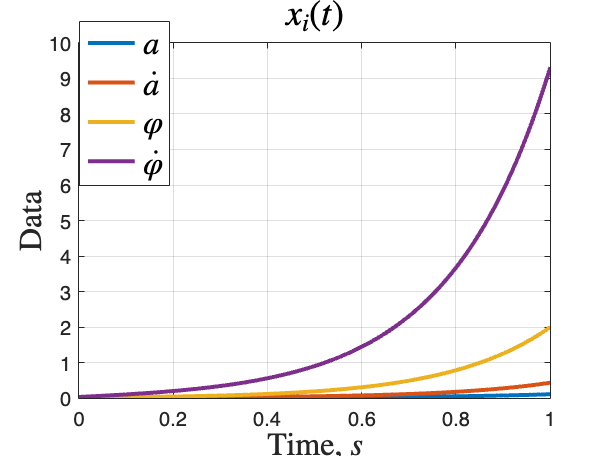

% Создание линейной системы
sys = ss(A, [B D], C, []);

% Начальное состояние
x0 = [0.01; 0.02; 0.03; 0.04]; % Начальное состояние

% Моделирование свободного движения системы
[y, t, x] = initial(sys, x0, [0:0.01:1]);

% Визуализация результатов
figure;
plot(t, x, LineWidth=2.0);
title('$x_i(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
legend('$a$', '$\dot{a}$','$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;

legend("Position", [0.15322,0.64804,0.10357,0.25119])

## **2.4 Нелинейное моделирование**

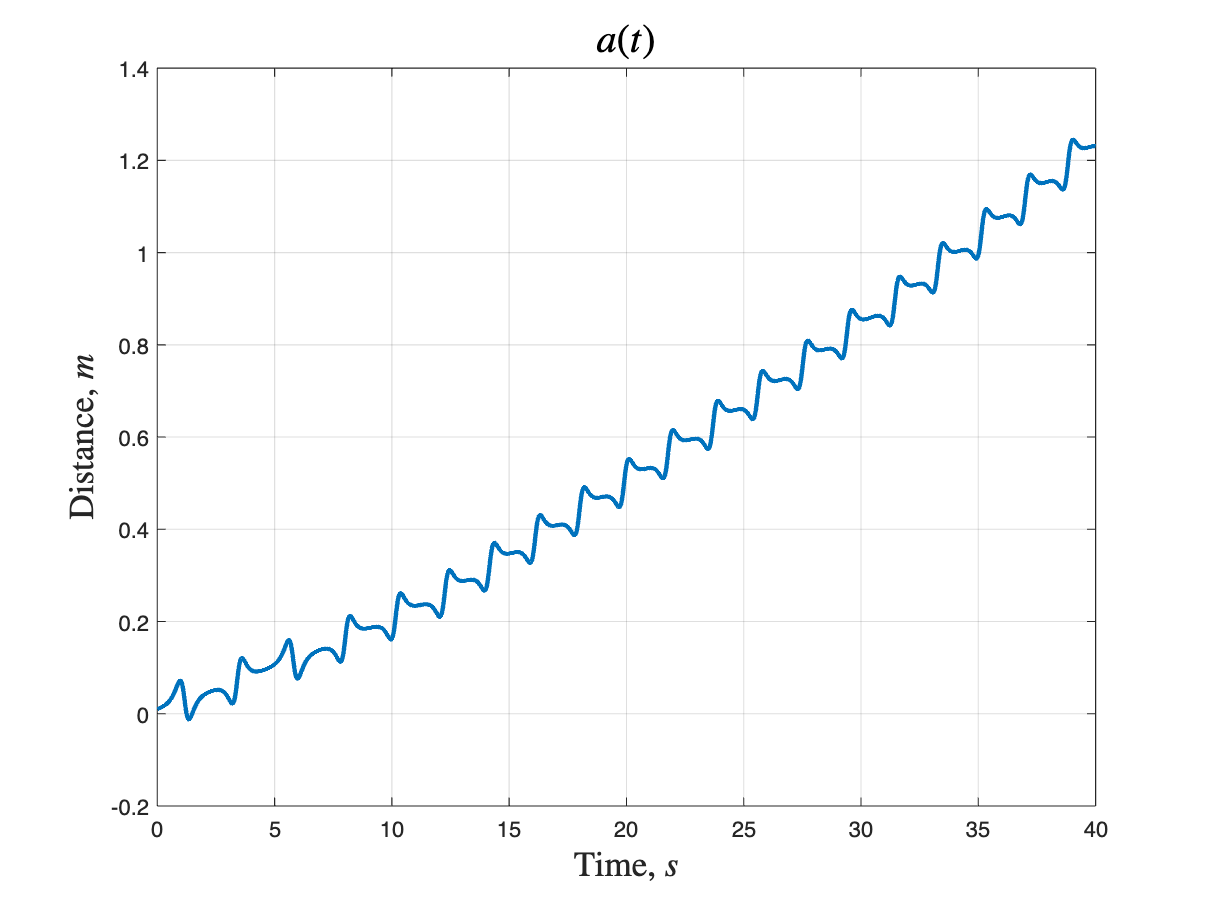

% Время моделирования
t_start = 0;
t_end = 40;
t_step = 0.01;
t = t_start:t_step:t_end;

% Начальные условия
x0 = [0.01; 0.02; 0.03; 0.04];

% Моделирование с помощью ode45
[t, states] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g), t, x0);
% Извлечение состояний системы
theta = states(:, 3);  % Угол отклонения маятника, рад
theta_dot = states(:, 4);  % Угловая скорость маятника, рад/с
x_pos = states(:, 1);  % Позиция тележки, м
x_dot = states(:, 2);  % Скорость тележки, м/с

% Визуализация
% График перемещения тележки
plot(t, x_pos, LineWidth=2.0);
% hold on;
% plot(t, x(:,1), LineWidth=2.0, LineStyle="--");
% legend('not linear', 'linear', 'Interpreter', 'latex', 'FontSize', 16);
title('${a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Distance, $m$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

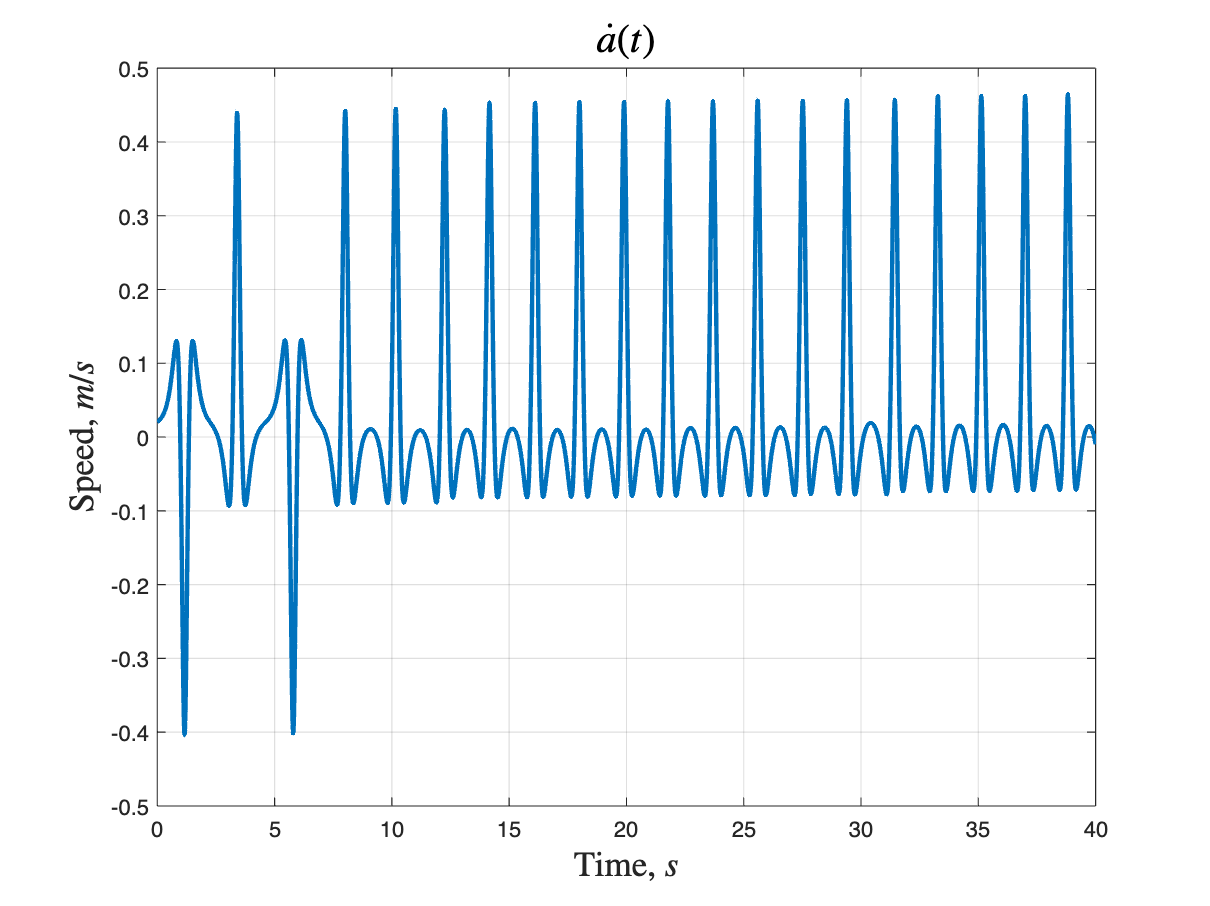


% График скорости тележки
plot(t, x_dot, LineWidth=2.0);
% hold on;
% plot(t, x(:,2), LineWidth=2.0, LineStyle="--");
% legend('not linear', 'linear', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Speed, $m/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

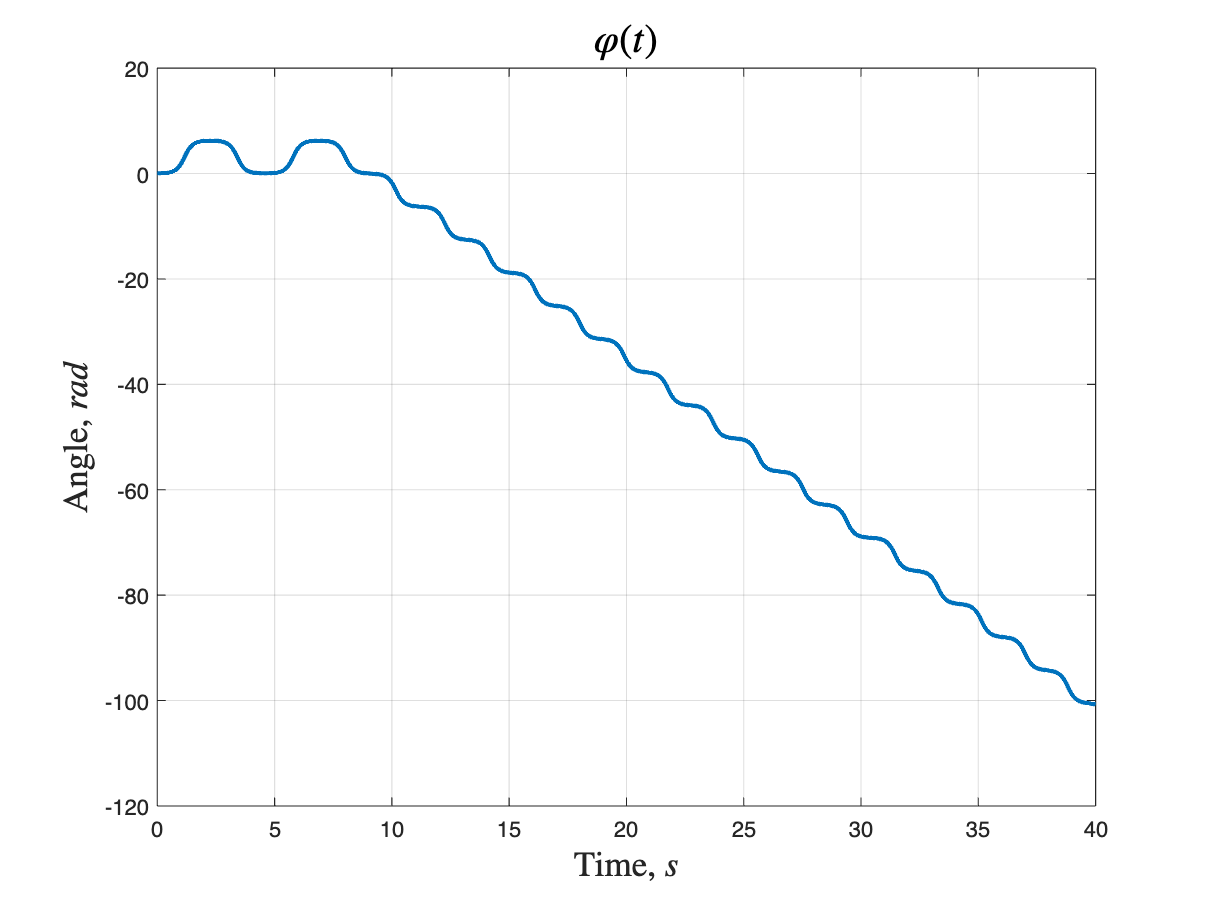


% График угла отклонения маятника
plot(t, theta, LineWidth=2.0);
% hold on;
% plot(t, x(:,3), LineWidth=2.0, LineStyle="--");
% legend('not linear', 'linear', 'Interpreter', 'latex', 'FontSize', 16);
title('$\varphi(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

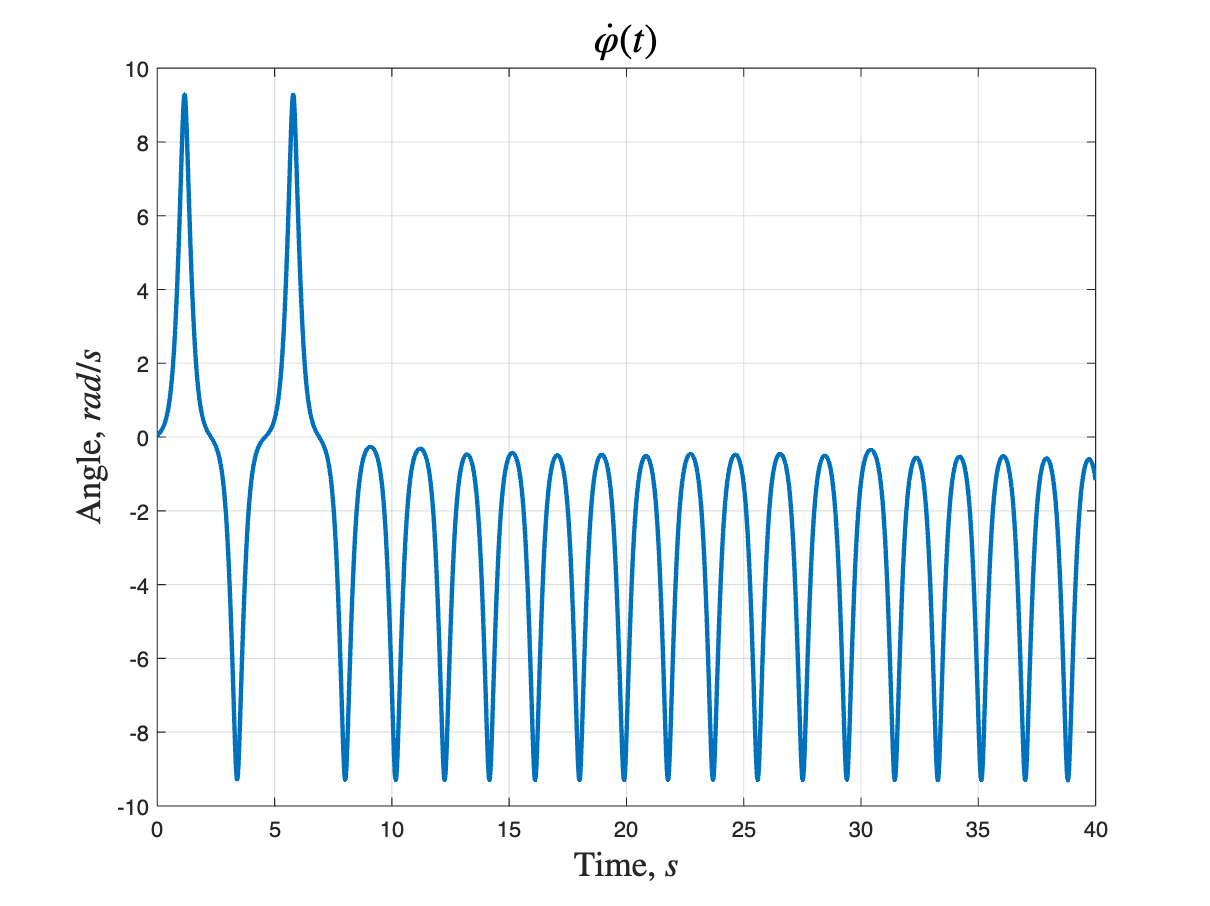


% График угловой скорости маятника
plot(t, theta_dot, LineWidth=2.0);
% hold on;
% plot(t, x(:,4), LineWidth=2.0, LineStyle="--");
% legend('not linear', 'linear', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{\varphi}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

function dx = pendulum_equations(t, x, m, M, l, g)
    % Состояния системы
    theta = x(3);  % Угол отклонения маятника
    theta_dot = x(4);  % Угловая скорость маятника
    x_pos = x(1);  % Позиция тележки
    x_dot = x(2);  % Скорость тележки

    % Вычисление производных состояний
    % ddtheta = (m*l*sin(theta)*x_dot^2 - (M+m)*g*sin(theta)) / ((M+m)*l - m*l*cos(theta)^2);
    % ddx = (m*l*cos(theta)*ddtheta - m*l*sin(theta)*theta_dot^2) / (M+m);
    ddtheta = ((M+m)/(l*(M+m*sin(theta)^2)))*((g*sin(theta)-(m*l*theta_dot^2*sin(theta)*cos(theta))/(M+m)));
    ddx = (1/(M+m*sin(theta)^2))*(m*g*sin(theta)*cos(theta)-m*l*theta_dot^2*sin(theta));

    % Составление вектора производных состояний
    dx = [x_dot; ddx;theta_dot; ddtheta];
end
